syms a1(t) a2(t) Y
m1 = 0.1;
m2 = 0.1;
l1 = 0.1;
l2 = 0.1;
g = 9.8;
Da1 = diff(a1,t);
D2a1 = diff(Da1,t);
Da2 = diff(a2,t);
D2a2 = diff(Da2,t);
eqn1 = (m1+m2)*l1^2*D2a1 + m2*l1*l2*D2a2 + (m1+m2)*g*l1*a1 == 0

$$eqn1(t) = \frac{49\,a_{1}\left(t\right)}{250}+\frac{\frac{\partial^{2}}{\partial t^{2}}a_{1}\left(t\right)}{500}+\frac{\frac{\partial^{2}}{\partial t^{2}}a_{2}\left(t\right)}{1000}=0$$

eqn2 = m2*l1*l2*D2a1 + m2*l2^2*D2a2 + m2*g*l2*a2 == 0

$$eqn2(t) = \frac{49\,a_{2}\left(t\right)}{500}+\frac{\frac{\partial^{2}}{\partial t^{2}}a_{1}\left(t\right)}{1000}+\frac{\frac{\partial^{2}}{\partial t^{2}}a_{2}\left(t\right)}{1000}=0$$

[VF,Subs] = odeToVectorField(eqn1, eqn2)

$$VF = \left(\begin{array}{c} Y_{2}\\ 196\,Y_{3}-196\,Y_{1}\\ Y_{4}\\ 98\,Y_{1}-196\,Y_{3} \end{array}\right)$$

$$Subs = \left(\begin{array}{c} a_{2}\\ {\mathrm{Da}}_{2}\\ a_{1}\\ {\mathrm{Da}}_{1} \end{array}\right)$$

odefcn = matlabFunction(VF, 'Vars',{t,Y})

odefcn = function_handle with value:
    @(t,Y)[Y(2);Y(1).*-1.96e+2+Y(3).*1.96e+2;Y(4);Y(1).*9.8e+1-Y(3).*1.96e+2]


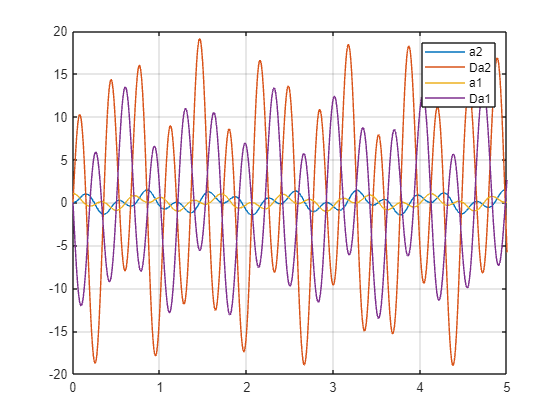

[X,Y] = ode45(odefcn, [0 5], [0 0 pi/3 0]);
figure
plot(X, Y)
grid
legend(string(Subs))